# trf_mkFigure 11

## Descriptions:

whichData = 'fmri1'; 
dataLoc   = fullfile(fileparts(temporalfMRIRootPath), 'files');

[a, b]    = loadfiles(dataLoc, whichData);
etc       = b.(whichData).etc;

roiNms = a.(whichData).nm;
nRois  = length(roiNms);

data  = squeeze(mean(a.fmri1.data));
param = etc.param;
t_isi    = etc.derivedParam.t_isi;
r_double = etc.derivedParam.r_double;


## Take average of data, model fit, and model parameters

mdata = mean(data, 2);
sdata = squeeze(std(data, [], 2));

for iroi = 1 : nRois
    idx = (iroi - 1) * 100 + 1 : iroi * 100;
    % average model predictions
    mprd(iroi, :) = mean(etc.prd(idx, :));
    sprd(iroi, :) = std(etc.prd(idx, :));
    
    % average model parameters
    mparam(iroi, :) = median(param(idx, 1 : 2));
    sparam(iroi, :, :) = prctile(param(idx, 1 : 2), [25, 75]); 
    
    % average the summary metrics
    m_tisi(iroi)    = median(t_isi(idx));
    m_rdouble(iroi) = median(r_double(idx));
    s_tisi(iroi, :)    = prctile(t_isi(idx), [25, 75]);
    s_rdouble(iroi, :) = prctile(r_double(idx), [25, 75]);
end


## Make figure 11

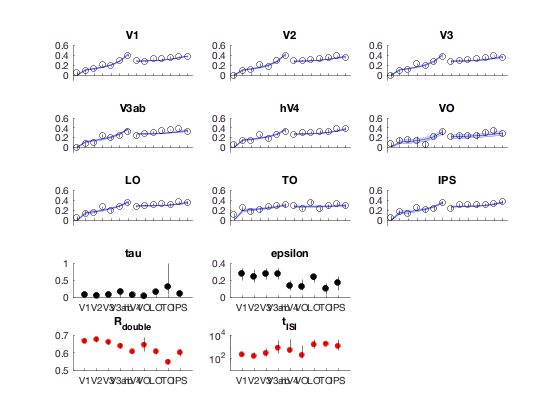

order = [13, 1 : 6, 5, 7 : 12];

figure (11), clf
% plot data and model fit
for iroi = 1 : nRois
   subplot(5, 3, iroi), cla
   % plot model prediction
   shadedErrorBar(1 : 7, mprd(iroi, order(1 : 7)), sprd(iroi, order(1 : 7)), 'b'), hold on
   shadedErrorBar(8 : 14, mprd(iroi, order(8 : 14)), sprd(iroi, order(8 : 14)), 'b')
   % plot data
   plot(mdata(iroi, order), 'ko'), 
   for k1 = 1 : length(order)
       plot([k1, k1], [mdata(iroi, order(k1))-sdata(iroi, order(k1)), mdata(iroi, order(k1))+sdata(iroi, order(k1))], 'k-')
   end
   box off, xlim([0.5, length(order) + 0.5]), ylim([-0.1, 0.6]), 
   set(gca, 'xaxislocation', 'origin', 'xtick', 1 : length(order), 'xticklabel', '', 'ytick', [0, 0.2, 0.4, 0.6])
   title(roiNms{iroi})
end
% plot model parameters
title_txt = {'tau', 'epsilon'};
for k = 1 : 2
    subplot(5, 3, 9 + k)
    plot(mparam(:, k), 'ko', 'markerfacecolor', 'k'), hold on
    for iroi = 1 : nRois
        plot([iroi, iroi], squeeze(sparam(iroi, :, k)), 'k')
    end
    box off, set(gca, 'xtick', 1 : nRois, 'xticklabel', roiNms), title(title_txt{k})
end
% plot summary metrics
title_txt = {'R_{double}', 't_{ISI}'};

subplot(5, 3, 13)
plot(m_rdouble, 'ro', 'markerfacecolor', 'r', 'markersize', 5), hold on
for iroi = 1 : nRois
    plot([iroi, iroi], s_rdouble(iroi, :), 'k-')
end
title(title_txt{1}), box off, set(gca, 'xtick', 1 : nRois, 'xticklabel', roiNms), title(title_txt{1})

subplot(5, 3, 14)
semilogy(m_tisi, 'ro', 'markerfacecolor', 'r', 'markersize', 5), hold on
for iroi = 1 : nRois
    semilogy([iroi, iroi], s_tisi(iroi, :), 'k-')
end
title(title_txt{2}), box off, set(gca, 'xtick', 1 : nRois, 'xticklabel', roiNms), ylim([10, 10^4])



% plot(mparam(:, k), 'ko', 'markerfacecolor', 'k'), hold on
% for iroi = 1 : nRois
%     plot([iroi, iroi], squeeze(sparam(iroi, :, k)), 'k')
% end
% box off, set(gca, 'xtick', 1 : nRois, 'xticklabel', roiNms), title(title_txt{k})

